yolo = yolov4ObjectDetector("csp-darknet53-coco");
yoloTiny = yolov4ObjectDetector("tiny-yolov4-coco");

img = imread("Rt9Frame1.png");


[bboxestiny, scorestiny, labelstiny] = detect(yoloTiny,img);
imgyolotiny = insertObjectAnnotation(img,"rectangle",bboxestiny,labelstiny);

[bboxes1, scores1, labels1] = detect(yolo,img);
imgyolo1 = insertObjectAnnotation(img,"rectangle",bboxes1,labels1);

[bboxes2, scores2, labels2] = detect(yolo,img,"Threshold",0.25);
imgyolo2 = insertObjectAnnotation(img,"rectangle",bboxes2,labels2);

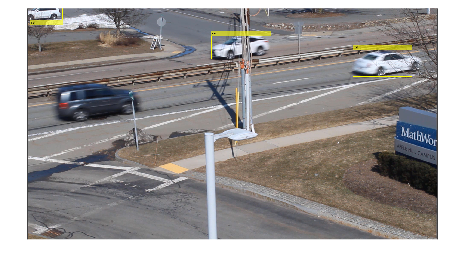

imshow(imgyolotiny)

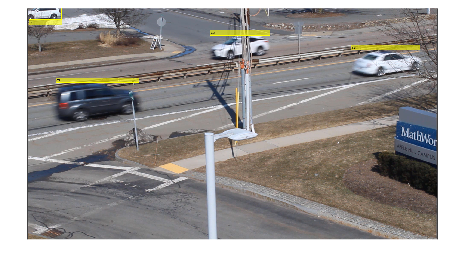

imshow(imgyolo1)

imshow(imgyolo2)